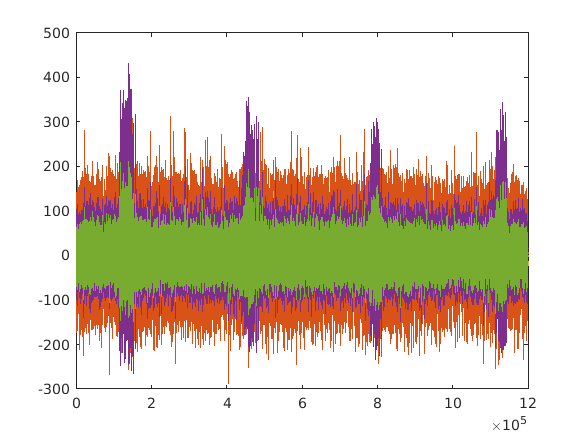

% MODE: BIPOLAR
% pos: e22
% neg: e64
% 
% WAVEFORM: 
% SHAPE: SQUARE BIPHASIC pos/neg
% DURATION/PHASE: 100 us ?
% AMPLITUDE/PHASE: 200 uA
% 
% ----------------------------
%
% 
% e22: labled ictal events only; interictal events are hidden in the baseline noise.
% 
% e64: labeled ictal events only; possibly, interictal events are hidden in the baseline noise.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Author: LilyHeAsamiko
% 
data1 = load('20171005_slice01_01_CTRL1_12.mat');
data2 = load('20171005_slice01_01_CTRL1_13.mat');
data3 = load('20171005_slice01_01_CTRL1_14.mat');
data4 = load('20171005_slice01_01_CTRL1_22.mat');

datalabel = load('20171005_slice01_01_CTRL1_12_ICTAL_LABELS.mat');

% data1 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_12.mat');
% data2 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_13.mat');
% data3 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_14.mat');
% data4 = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_mat_files\20171005_slice01_01_CTRL1_22.mat');
% 
% datalabel = load('D:\TUT\Medical\biophysics\NolinearTimeSeriesAnalysis-new\data\20171005\01\20171005_01_LABELS\20171005_slice01_01_CTRL1_12_ICTAL_LABELS.mat');

fs = data1.fs;
MEA1 = data1.data;
MEA2 = data2.data;
MEA3 = data3.data;
MEA4 = data4.data;

ictals = table2array(datalabel.labels);
N = length(MEA1);%sample number
T = N/fs; %600s
bin = N/T; %samples per bin(1s)
N_bin = N/bin; % bin number
ch = 1;%12 13 14 22

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % tonic seizure
% % 3min , 1min pre-seizure, 1min seizure, 1min post-seizure
% MEA0 = data0.data0.data;
% MEA1 = data.data.data;
% seizures0 = table2array(data0.data0.labels);
% seizure1 = table2array(data.data.labels);
% fs = data0.data0.fs
% 
% N = length(MEA0);%sample number
% T = N/fs; %180 s
% bin = N/T; %samples per bin(1s)
% N_bin = N/bin; % bin number
% ch = 1;%1 0

MEA_avg = mean([MEA1, MEA2, MEA3, MEA4], 2);
figure
%% onset detection
% average of the multi-channels

plot(MEA1)
hold on
plot(MEA2)
hold on
plot(MEA3)
hold on
plot(MEA4)
hold on
plot(MEA_avg)

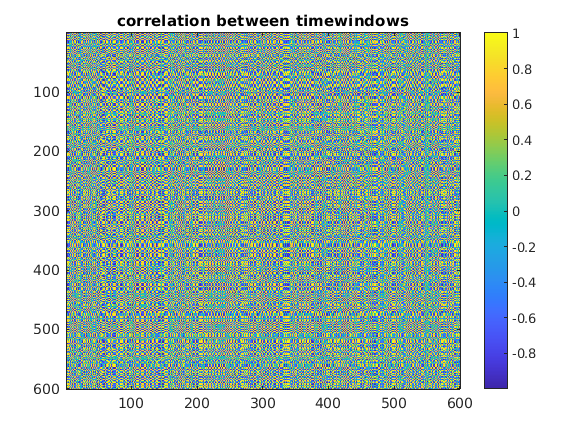


MEA_t = [MEA1 MEA2 MEA3 MEA4 MEA_avg];
for win = 1: N_bin    
    MEA_t_avg(win, :) = mean(MEA_t((win-1)*bin+1:(win-1)*bin+bin,:),1);
end

% %%%%%%%
% %another
% figure
% plot(MEA0)
% hold on
% plot(MEA1)
% 
% MEA_t = [MEA0 MEA1];
% for win = 1: N_bin    
%     MEA_t_avg(win, :) = mean(MEA_t((win-1)*bin/2+1:(win-1)*bin/2+bin,:),1);
% end

% onset based on decorrelation time: the first t ensures, local minimum of
% autocorrelation: abs(corr< 1/e),  here let e be 2
[rho,pval] = corr(MEA_t_avg');
figure,
%pcolor(rho);
imagesc(rho)
title('correlation between timewindows');
rho_dec = min(find(rho < 0.5));
t_onset = rho_dec;        
colorbar

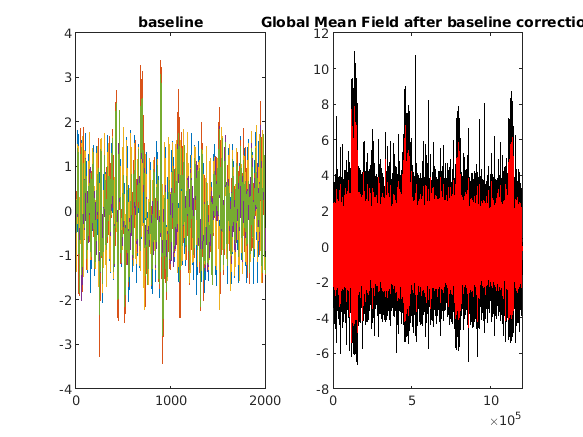


%[minr, t_row] = min(abs(rho));
%[minrho, t_col] = min(minr);
%t_onset = min(t_col,t_row(t_col));

% onset based on ictals label
% onset_lb = floor(ictals(1));
% if t_onset > onset_lb
%    t_onset = onset_lb; 
% end
onset = (t_onset-1)*fs;

MEA_seizure = MEA_t(onset+1: N,:); 
MEA_ch = MEA_seizure(:,1);
%  baseline_corrected
MEA_seizure0 = MEA_seizure - repmat(mean(MEA_t_avg(1: t_onset,:), 1),size(MEA_seizure,1), 1);
% Z-score Normalization
MEA_seizure = MEA_seizure0./std(MEA_seizure0, 1);
% GMFP
m = mean(MEA_seizure, 2);
GMF = m;
k = length(MEA_seizure);
%GMF = sqrt(mean((MEA_seizure-repmat(m, 1, size(MEA_seizure, 2))).^2,2)); 

figure,
subplot(1, 2, 1)
plot(1:onset,MEA_seizure(1:onset,:));
%note wrong: xlim([0 onset+10])
%xticks(int32(1: k/7: onset))
title('baseline');
subplot(1, 2, 2)
plot(onset+1: N, MEA_seizure,'k');
hold on;
plot(onset+1: N, GMF,'r');
%xlim([onset+1 k+10+onset+1])
%xticks(int32(onset+1: k/5: N))
%xticklabels(num2str(onset+1: k/5: N))
title('Global Mean Field after baseline correction');

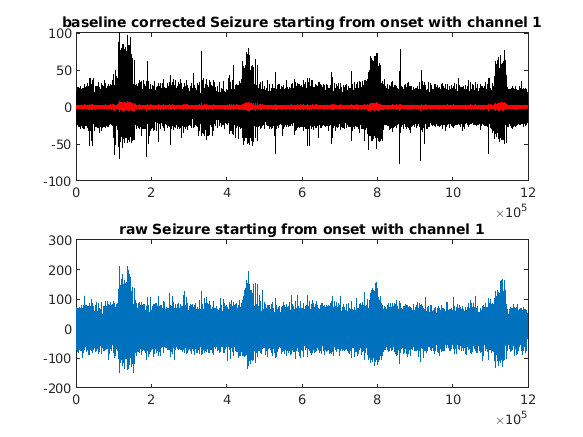


MEAy_ch = MEA_seizure0(:,ch);
Pnts = length(MEAy_ch);
figure,
subplot(2, 1, 1)
plot(MEAy_ch, 'k')
hold on
plot(GMF,'r')
title(['baseline corrected Seizure starting from onset with channel ',num2str(ch)]);
subplot(2, 1, 2)
plot(MEA_avg(onset+1: N))
title(['raw Seizure starting from onset with channel ',num2str(ch)]);

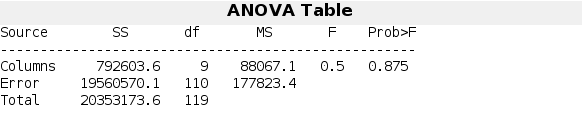

p = 0.8750

tbl = 4×6 cell array
    {'Source' }    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[7.9260e+05]}    {[  9]}    {[8.8067e+04]}    {[  0.4953]}    {[  0.8750]}
    {'Error'  }    {[1.9561e+07]}    {[110]}    {[1.7782e+05]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[2.0353e+07]}    {[119]}    {0×0 double  }    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: [10×2 char]
         n: [12 12 12 12 12 12 12 12 12 12]
    source: 'anova1'
     means: [108.8614 194.1596 90.0485 39.0010 206.6606 52.5040 207.6077 243.6238 246.4777 272.4302]
        df: 110
         s: 421.6911


%% count spikes 
threshold = 10;% spike: >10 muV
%threshold = 20;
delta = [0.5, 3];
theta = [4, 7];
alpha = [8, 12];
mu = [7.5, 12.5];
SMR = [12.5, 15.5];
beta = [16, 31];
gamma = [32, 100];

t = -0.5:1/fs:0.5;  % Time vector 
L = length(t)-1;      % Signal length
X = 1/(4*sqrt(2*pi*0.01))*(exp(-t(1:L).^2/(2*0.01)));

figure,
plot(t(1:L),X)
title('Gaussian Pulse in Time Domain')
xlabel('Time (t)')
ylabel('X(t)')
%single spikes
%Ns = length(MEAy_ch(MEAy_ch > threshold));

N_bin = ceil(Pnts/bin);
chf_bin_d = zeros(N_bin, bin); 
chf_bin_th = zeros(N_bin, bin); 
chf_bin_a = zeros(N_bin, bin); 
chf_bin_m = zeros(N_bin, bin); 
chf_bin_s = zeros(N_bin, bin); 
chf_bin_b = zeros(N_bin, bin); 
chf_bin_g = zeros(N_bin, bin); 

chn_bin = zeros(N_bin, bin);
chf_bin = zeros(N_bin, bin);
MEAs_chft = zeros(N_bin, 0.5*bin);
MEAs_chsd = zeros(N_bin, 0.5*bin);

Ns_chn_bin = zeros(N_bin,1); 
Nsft_chn_bin = zeros(N_bin,1); 
Nssd_chn_bin = zeros(N_bin,1); 
MEAs_chf = zeros(N_bin, bin);   

fn = 0:bin-1;
f = 1.0*double(fn)/double(bin-1);

Chf_bin_d = find(f > (delta(1)/fs) & f < (delta(2)/fs));
Chf_bin_th = find(f > (theta(1)/fs) & f < (theta(2)/fs));
Chf_bin_a = find(f > (alpha(1)/fs) & f < (alpha(2)/fs));
Chf_bin_m = find(f > (mu(1)/fs) & f < (mu(2)/fs));
Chf_bin_s = find(f > (SMR(1)/fs) & f < (SMR(2)/fs));
Chf_bin_b = find(f > (beta(1)/fs) & f < (beta(2)/fs));
Chf_bin_g = find(f > (gamma(1)/fs) & f < (gamma(2)/fs));
if mod(Pnts, bin) > 0
    N_bin = ceil(Pnts/bin);
else
    N_bin = Pnts/bin;
end



%per second                       
for n = 1: N_bin
%    nn = 2*n-1;
    if n == N_bin
       if length(bin*(n-1)+1:Pnts) < bin
            MEAs_chn = [MEA_ch(bin*(n-1)+1:Pnts); zeros(bin-length(bin*(n-1)+1:Pnts), 1)];
       else
            MEAs_chn = MEA_ch(bin*(n-1)+1:Pnts);
       end
       MEAs_chft(n,:) = MEAs_chn(1:0.5*bin)'; %
       MEAs_chsd(n,:) = MEAs_chn(0.5*bin+1:bin)';
%         %test
%         MEAs_testn = MEA_test(bin*(n-1)+1:Pnts);
%         MEAs_testft = MEA_test(0.5*bin*(nn-1)+1:0.5*bin*nn);
%         MEAs_testsd = MEA_test(0.5*bin*nn+1:Pnts);
    else
       MEAs_chn = MEA_ch(bin*(n-1)+1:bin*n);
       MEAs_chft(n,:) = MEAs_chn(1:0.5*bin)'; %
       MEAs_chsd(n,:) = MEAs_chn(0.5*bin+1:bin)';
%        MEAs_chft = MEA_ch(0.5*bin*(n-1)+1:0.5*bin*n);
%        MEAs_chsd = MEA_ch(0.5*bin*n+1:0.5*bin*(n+1));
        %test
%         MEAs_testn = MEA_test(bin*(n-1)+1:bin*n);
%         MEAs_testft = MEA_test(0.5*bin*(nn-1)+1:0.5*bin*nn);
%         MEAs_testsd = MEA_test(0.5*bin*nn+1:0.5*bin*(nn+1));        
    end
    size(fft(MEAs_chn'));
    if length(fft(MEAs_chn))< length(MEAs_chf(n,:))
        FFT_MEAs_chn = [fft(MEAs_chn') zeros(1, length(MEAs_chf(n,:))-length(fft(MEAs_chn)))];
        EXT_MEAs = [MEAs_chn' zeros(1, length(MEAs_chf(n,:))-length(MEAs_chn))];
    else
        FFT_MEAs_chn = fft(MEAs_chn');
        EXT_MEAs = MEAs_chn';
    end
    size(X);
    MEAs_chf(n,:) = FFT_MEAs_chn.*X;
%!!
%     chf_bin_d(n,:) = abs(MEAs_chf(n,:)) > delta(1) & abs(MEAs_chf(n,:)) < delta(2);
%     chf_bin_th(n,:) = abs(MEAs_chf(n,:)) > theta(1) & abs(MEAs_chf(n,:)) < theta(2);
%     chf_bin_a(n,:) = abs(MEAs_chf(n,:)) > alpha(1) & abs(MEAs_chf(n,:)) < alpha(2);
%     chf_bin_m(n,:) = abs(MEAs_chf(n,:)) > mu(1) & abs(MEAs_chf(n,:)) < mu(2);
%     chf_bin_s(n,:) = abs(MEAs_chf(n,:)) > SMR(1) & abs(MEAs_chf(n,:)) < SMR(2);
%     chf_bin_b(n,:) = abs(MEAs_chf(n,:)) > beta(1) & abs(MEAs_chf(n,:)) < beta(2);
%     chf_bin_g(n,:) = abs(MEAs_chf(n,:)) > gamma(1) & abs(MEAs_chf(n,:)) < gamma(2);
    
    chf_bin(n,abs(EXT_MEAs) > threshold & fft(EXT_MEAs)> 0.5) = abs(fft(EXT_MEAs(abs(EXT_MEAs) > threshold & fft(EXT_MEAs)> 0.5)));
    chf_bin_d(n,Chf_bin_d) = abs(MEAs_chf(n, Chf_bin_d));
    chf_bin_th(n,Chf_bin_th) = abs(MEAs_chf(n, Chf_bin_th));
    chf_bin_a(n,Chf_bin_a) = abs(MEAs_chf(n, Chf_bin_a));
    chf_bin_m(n,Chf_bin_m) = abs(MEAs_chf(n, Chf_bin_m));
    chf_bin_s(n,Chf_bin_s) = abs(MEAs_chf(n, Chf_bin_s));
    chf_bin_b(n,Chf_bin_b) = abs(MEAs_chf(n, Chf_bin_b));
    chf_bin_g(n, Chf_bin_g) = abs(MEAs_chf(n, Chf_bin_g));
   
    Ns_chn_bin(n) = length(MEAs_chn(abs(MEAs_chn) > threshold));
    Nsft_chn_bin(n) = length(MEAs_chft(abs(MEAs_chft) > threshold));
    Nssd_chn_bin(n) = length(MEAs_chsd(abs(MEAs_chsd) > threshold));    
    chn_bin(n,:) = EXT_MEAs.*(abs(EXT_MEAs) > threshold); 
    if n == N_bin 
        break;
    end
end
[chns_rho,chns_p] = corr(chn_bin);
[chf_rho,chf_p] = mscohere(chf_bin, chf_bin);
% [chnsd_rho,chnsd_p] = corr(chf_bin_d);
% [chnsth_rho,chnsth_p] = corr(chf_bin_th);
% [chnsa_rho,chnsa_p] = corr(chf_bin_a);
% [chnsm_rho,chnsm_p] = corr(chf_bin_m);
% [chnss_rho,chnss_p] = corr(chf_bin_s);
% [chnsb_rho,chnsb_p] = corr(chf_bin_b);
% [chnsg_rho,chnsg_p] = corr(chf_bin_g);

Ns = sum(Ns_chn_bin);

[chnsd_rho,chnsd_p] = mscohere(chf_bin_d, chf_bin_d);
[chnsth_rho,chnsth_p] = mscohere(chf_bin_th, chf_bin_th);
[chnsa_rho,chnsa_p] = mscohere(chf_bin_a, chf_bin_a);
[chnsm_rho,chnsm_p] = mscohere(chf_bin_m, chf_bin_m);
[chnss_rho,chnss_p] = mscohere(chf_bin_s, chf_bin_s);
[chnsb_rho,chnsb_p] = mscohere(chf_bin_b, chf_bin_b);
[chnsg_rho,chnsg_p] = mscohere(chf_bin_g, chf_bin_g);
    
%0 black
figure,
subplot(3,3,1)
imshow(chn_bin==0);
title('stim(time) v.s bins(per ms)')
subplot(3,3,2)
imshow(chf_bin==0);
title('stim(freq) v.s bins(per ms)')
subplot(3,3,3)
imshow(chf_bin_d==0);
title('Delta band: stim(Hz) v.s bins(per ms)')
subplot(3,3,4)
imshow(chf_bin_th==0);
title('Theta band: stim(Hz) v.s bins(per ms)')
subplot(3,3,5)
imshow(chf_bin_a==0);
title('Alpha band: stim(Hz) v.s bins(per ms)')
subplot(3,3,6)
imshow(chf_bin_m==0);
title('Mu band: stim(Hz) v.s bins(per ms)')
subplot(3,3,7)
imshow(chf_bin_s==0);
title('SMR band: stim(Hz) v.s bins(per ms)')
subplot(3,3,8)
imshow(chf_bin_b==0);
title('Beta band: stim(Hz) v.s bins(per ms)')
subplot(3,3,9)
imshow(chf_bin_g==0);
title('Gamma band: stim(Hz) v.s bins(per ms)')
figure,
subplot(2,2,1)
hist(Ns_chn_bin);
title('histogram: spikes v.s bins(per ms)')
subplot(2,2,2)
bar([Nsft_chn_bin,Nssd_chn_bin]);
title('PSTH: stim number(first half & second half) v.s time(per ms)')
subplot(2,2,3)
bar(autocorr([Nsft_chn_bin', Nssd_chn_bin']));
title('ACG: autocorelagrm(first half & second half) v.s time(per ms)')
subplot(2,2,4)
bar([autocorr(Nsft_chn_bin), autocorr(Nssd_chn_bin)]);
title('ACG: autocorelagrm(half ms) v.s time(per ms)')
figure,
subplot(3,3,1)
imagesc(chns_rho);
title('ACG(time) v.s bins(per ms)')
colorbar
subplot(3,3,2)
imagesc(chf_rho);
title('ACG(freq) v.s bins(per ms)')
colorbar
subplot(3,3,3)
imagesc(chnsd_rho);
title('Delta band: ACG v.s bins(per ms)')
colorbar
subplot(3,3,4)
imagesc(chnsth_rho);
title('Theta band: ACG v.s bins(per ms)')
colorbar
subplot(3,3,5)
imagesc(chnsa_rho);
title('Alpha band: ACG v.s bins(per ms)')
colorbar
subplot(3,3,6)
colorbar
imagesc(chnsm_rho);
title('Mu band: ACG v.s bins(per ms)')
colorbar
subplot(3,3,7)
imagesc(chnss_rho);
title('SMR band: ACG v.s bins(per ms)')
colorbar
subplot(3,3,8)
imagesc(chnsb_rho);
title('Beta band: ACG v.s bins(per ms)')
colorbar
subplot(3,3,9)
imagesc(chnsg_rho);
title('Gamma band: ACG v.s bins(per ms)')
colorbar
%ylabel(Stim)

% spike train: >5 spikes in one interval
% mark (laptop does not take correct v)
interval = bin/10;% interval: 100ms
if mod(Pnts, interval) > 0
    Nint = floor(Pnts/interval);
else
    Nint = Pnts/interval;
end
Nt_int = zeros(Nint, 1);
s_int = zeros(interval,Nint);
Nr_int = zeros(interval,Nint);
 
for n = 1: Nint
    nn = 2*n - 1;
    if n == Nint
        MEAint_ch = [MEA_ch(interval*(n-1)+1:Pnts); zeros(length(interval) - length(interval*(n-1)+1:Pnts), 1)];
%        MEAint_ch = MEA_ch(interval*(n-1)+1:Pnts);
    else
        MEAint_ch = MEA_ch(interval*(n-1)+1:interval*n);
    end
    Ns_int = length(MEAint_ch(abs(MEAint_ch) > threshold));
    if (Ns_int > 5)
        Nt_int(n) = Ns_int;
        s_int(:,n) = Ns_int.*(abs(MEAint_ch) > threshold);        
        Nr_int(:,n) = MEAint_ch.*(abs(MEAint_ch) > threshold);
    end
end
Ntr = sum(Nt_int);
[chni_rho,chni_p] = corr(Nr_int);
figure,
subplot(3,1,1)
imagesc(Nr_int);
title('spike train values v.s. per interval(100ms)')
subplot(3,1,2)
imagesc(s_int==0);
title('spike train distribution(spikes) v.s. per interval(100ms)')
subplot(3,1,3)
imagesc(chni_rho);
title('Correlation v.s. per interval(100ms)')
colorbar

% burst: >30 spikes in one period(500 ms with inter-spike interval less than 20 ms)
interval2 = round(interval/5);
period = 5*interval;

if mod(Pnts, period) > 0
    Nperiod = floor(Pnts/period) + 1;
else
    Nperiod = Pnts/period;     
end
Nb_per_int2 = zeros(Nperiod,1);
b_per_int2 = zeros(period,Nperiod);

if mod(period, interval2) > 0
    Nint2 = floor(period/interval2) + 1;
else 
    Nint2 = period/interval2;
end

for n = 1: Nperiod
    if n == Nperiod
        MEAper_ch = [MEA_ch(period*(n-1)+1:Pnts);zeros(length(period) - length(period*(n-1)+1:Pnts))];
    else
        MEAper_ch = MEA_ch(period*(n-1)+1:period*n);
    end
    Nb_per = zeros(Nint2,1);
    b_per = zeros(interval2,Nint2);
    for nn = 1: Nint2
        if nn == Nint2
            MEAper_int2_ch = [MEAper_ch(interval2*(nn-1)+1:interval2*nn);zeros(length(interval2) - length(interval2*(nn-1)+1:interval2*nn))];
        else
        	MEAper_int2_ch = MEAper_ch(interval2*(nn-1)+1:interval2*nn);
        end
        Nb_per(nn) = length(MEAper_int2_ch(abs(MEAper_int2_ch) > threshold));
        if nn > 1
            if Nb_per(nn-1)*Nb_per(nn) == 0
                Nb_per(nn) = 0;
            elseif nn < Nint2
                b_per(:, nn) = MEAper_int2_ch.*(abs(MEAper_int2_ch) > threshold);
            else
                b_per(1:interval2, nn) = MEAper_int2_ch.*(abs(MEAper_int2_ch) > threshold);
            end
        end         
    end    
%    MEAper2_int2_ch = MEAper_ch(interval2*Nint2+1:interval2*Nint2+interval2);
    Nb_per_int2(n) = sum(Nb_per); 
    temp = b_per.*(b_per ~= 0);
    b_per_int2(:,n) = temp(:);
end
Nburst = sum(Nb_per_int2);
[chnp_rho,chnp_p] = corr(b_per_int2);
figure,
subplot(3,1,1)
hist(Nb_per_int2);
title('histogram: bursts (>30 spikes in one period(500 ms) with inter-spike interval less than 20 ms)')
subplot(3,1,2)
imagesc(b_per_int2);
title('bursts intensity per period(500 ms)')
colorbar
subplot(3,1,3)
imagesc(chnp_rho);
title('correlation v.s. per period(500 ms)')
colorbar
figure,
subplot(3,1,1)
bar(Ns_chn_bin);
title(['raw data on channel ', num2str(ch),'with', num2str(length(Ns_chn_bin)), 'spikes in each second']);
subplot(3,1,2)
bar(Nt_int);
title(['raw data on channel ', num2str(ch),'with ', num2str(length(Nt_int)), 'train spikes in each interval: 100 ms']);
subplot(3,1,3)
bar(Nb_per_int2);
title(['raw data on channel ', num2str(ch),'with ', num2str(length(Nb_per_int2)), 'bursts in each period: 500 ms']);
%display(['raw data on channel ', num2str(ch), ' ', 'has ', num2str(Ns),' single spikes,', num2str(Ntr),' spike trains and ', num2str(Nburst),' bursts'])

% preprocess
winlen = bin; %samples per window
b = (1/winlen)*ones(1,winlen);
a = 1;

%filter
MEA_t = filter(b, a, MEAy_ch);
plot(MEAy_ch,'k');
hold on
plot(MEA_t,'r');
%spikes of ictals (narrow and broad with/without filter)
asym = zeros(length(ictals(:)),1);
dur = zeros(length(ictals(:)),1);
starts = ictals(:,1);
ends = ictals(:,2);
gap = cell(length(ictals(:)));
NBIN = zeros(length(ictals(:)),1);


for n = 1:length(ictals(:))
    if mod(n, 2) == 1
        nbin = floor(starts((n+1)/2));
    else
        nbin = floor(ends(n/2));
    end

    NBIN(n) = nbin;
    
    MEA_ictal_bin = zeros(bin,1);
    
    n_interv = (nbin-5)*bin: (nbin+5)*bin;
    MEA_ictal_bin = MEA_t(bin*(nbin-1)+1:bin*nbin);
    fire_n_interv(:,n)= MEA_ictal_bin;
    
    au = chns_rho(:, nbin);
    aud = chnsd_rho(:, nbin);
    auth = chnsth_rho(:, nbin);
    aua = chnsa_rho(:, nbin);
    aum = chnsm_rho(:, nbin);
    aus = chnss_rho(:, nbin);
    aub = chnsb_rho(:, nbin);
    aug = chnsg_rho(:, nbin);

    figure,
    subplot(2,3,1)
    plot(au)
    hold on
    plot(aud)
    hold on
    plot(auth)
    hold on
    plot(aua)
    hold on
    plot(aum)
    hold on
    plot(aus)
    hold on
    plot(aub)
    hold on
    plot(aug)
    title(['correlation between bin: ', num2str(nbin), ' and other bins']);
    legend([{'time'},{'delta'},{'theta'},{'alpha'},{'mu'},{'smr'},{'beta'},{'gamma'}]);
    
    [auh, Bin] = hist(au);
    subplot(2,3,2)
    hist(au)
    title(['histogram: correlation between bin: ', num2str(nbin), ' and other bins']);


    subplot(2,3,3)
    qa1 = quantile(au, 0);
    qa2 = quantile(au, 0.75);
    gapn = au(au <= qa2 & au >= qa1);
    Bini = find(au <= qa2 & au >= qa1);
    [count, center] = hist(gapn);
    for i = 1:length(center)
        B(1+(i-1)*length(Bini(abs(gapn - center(i))< 0.1)):i*length(Bini(abs(gapn - center(i))< 0.1))) = Bini(abs(gapn - center(i))< 0.1);
    end
    gap{n} = hist(B(B > 0));
    subplot(2,3,3)
    hist(gap{n})
    title(['histogram: gap of bin: ', num2str(nbin)]);
    clear B gapn Bini count center
    
    subplot(2,3,4)
    plot(MEAy_ch(n_interv),'r');
    hold on
    plot(MEA_t(n_interv),'b');
    if mod(n,2) == 1
        title(['raw data v.s filtered data on channel ', num2str(ch),' around ', num2str(nbin), ' th bin i.e. ', num2str(n), ' th ictal starting point']);
    else
        title(['raw data v.s filtered data on channel ', num2str(ch),' around ', num2str(nbin), ' th bin i.e. ', num2str(n), ' th ictal ending point']);
    end
    legend('Input Data','Filtered Data')
    
        
    subplot(2,3,5)
    pspectrum(MEA_ictal_bin);
    title(['spectrogram on channel ', num2str(ch),' from ', num2str(nbin), ' th bin : ', num2str(nbin-5),' ms to ', num2str(nbin+5), ' ms']);

    [phi,w] = phasez(MEA_ictal_bin);
    A = abs(MEAs_chf(:,nbin));
    
    subplot(2,3,6)
    polarplot(phi,A(1:length(phi)));
    title(['phase after FFT with Gaussian window on channel ', num2str(ch),' around ', num2str(nbin), ' th bin : ', num2str(nbin-5),' ms', num2str(nbin+5), ' ms']);
    
    [pks, locs] = findpeaks(MEA_ictal_bin);
    [MAX, MAXI] = max(MEA_ictal_bin);
    [MIN, MINI] = min(MEA_ictal_bin);
    a = MAX - MIN;
    b = pks(length(pks)) - MIN;
    asym(n) = (a - b)/(a + b);
    dur(n) = locs(length(pks)) - MINI;
end
CORRTF= [chns_rho(:,NBIN);chnsd_rho(:,NBIN);chnsth_rho(:,NBIN);chnsa_rho(:,NBIN);chnsm_rho(:,NBIN);chnss_rho(:,NBIN);chnsb_rho(:,NBIN);chnsg_rho(:,NBIN)];

% figure,
% subplot(3,2,1)
% bar(asym);
% title('asymmetry');
% subplot(3,2,2)
% bar(dur);
% title('duration');

for n = 1: length(ictals(:))
    Q3BIN(n) = gap{n}(length(ictals(:)));
    QBINDIST(n) = abs(gap{n}(length(ictals(:)))- gap{n}(1));
    TrSIGMADIST(n) = abs(gap{n}(length(ictals(:)))- NBIN(n));
    MaxIctal(n) = max(abs(fire_n_interv(:, n)),[],1);
    MinIctal(n) = min(abs(fire_n_interv(:, n)),[],1);
    StdIctal(n) = std(abs(fire_n_interv(:, n)),1);
end


CORRTF= CORRTF(:,1:10);
MeanCorr = mean(abs(CORRTF),1);
StdCorr = std(abs(CORRTF),1);
type = ["broad","broad", "broad", "narrow",  "broad","narrow","broad","broad","broad","broad"];
%X = [NBIN; Q3BIN;QBINDIST; TrSIGMADIST;ictal_n_interv;CORRTF];
X1 = [asym'; dur'; NBIN'; Q3BIN;QBINDIST; TrSIGMADIST;MaxIctal;MinIctal;StdIctal;MeanCorr;StdCorr;[-1,-1,-1,1,-1,1,-1,-1,-1,-1]];
%X(isnan(X))= 0;
X1(isnan(X1))= 0;

%%
%[asym_test,dur_test,NBIN_test,Q3BIN_test,QBINDIST_test,TrSIGMADIST_test,fire_n_interv_test,CORRTF_test,MaxIctal_test,MinIctal_test,StdIctal_test,MeanCorr_test,StdCorr_test] = spikes(Pnts, bin, fs, test, MEA_test, MEAy_test, ictals4)
%%
y = [-1,-1,-1,1,-1,1,-1,-1,-1,-1];
%X = [NBIN; Q3BIN;QBINDIST; TrSIGMADIST;ictal_n_interv;CORRTF];
%X1 = [asym'; dur'; NBIN; Q3BIN;QBINDIST; TrSIGMADIST;MaxIctal;MinIctal;StdIctal;MeanCorr;StdCorr;y];
%X(isnan(X))= 0;
%X1(isnan(X1))= 0;

NNBIN = size(NBIN,1);
NQ3BIN = size(Q3BIN,1);
NQBINDIST = size(QBINDIST,1);
NTrSIGMADIST = size(TrSIGMADIST,1);
Nfire_n_interv = size(fire_n_interv,1);
NCORRTF = size(CORRTF,1);
NMaxIctal = size(MaxIctal,1);
NMinIctal  = size(MinIctal ,1);
NStdIctal = size(StdIctal,1);
NMeanCorr  = size(MeanCorr ,1);
NStdCorr  = size(StdCorr ,1);
%type'
group = [0;0;0;1;0;1;0;0;0;0];

R = corr(X1);
[p,tbl,stats] = anova1(X1)

[results,means] = multcompare(stats,'CType','bonferroni')

results =     1.0000    2.0000 -661.8589  -85.2982  491.2626    1.0000
    1.0000    3.0000 -557.7478   18.8129  595.3737    1.0000
    1.0000    4.0000 -506.7003   69.8605  646.4212    1.0000
    1.0000    5.0000 -674.3599  -97.7992  478.7615    1.0000
    1.0000    6.0000 -520.2033   56.3574  632.9182    1.0000
    1.0000    7.0000 -675.3070  -98.7463  477.8144    1.0000
    1.0000    8.0000 -711.3231 -134.7623  441.7984    1.0000
    1.0000    9.0000 -714.1770 -137.6162  438.9445    1.0000
    1.0000   10.0000 -740.1295 -163.5688  412.9920    1.0000
    2.0000    3.0000 -472.4496  104.1111  680.6718    1.0000


means =   108.8614  121.7317
  194.1596  121.7317
   90.0485  121.7317
   39.0010  121.7317
  206.6606  121.7317
   52.5040  121.7317
  207.6077  121.7317
  243.6238  121.7317
  246.4777  121.7317
  272.4302  121.7317


stats=gplotmatrix(X1',[],group,[],'*.')

stats =   12×12×2 graphics array.



Tbtimelm = table(X1(1,:)',X1(2,:)',X1(3,:)',X1(4,:)',X1(5,:)',X1(6,:)',X1(7,:)',X1(8,:)',X1(9,:)',X1(10,:)',X1(11,:)',group,'VariableNames',{'Asymetry','Duration','spikeBIN','Q3BIN','DIST_Q3', 'DIST_3SIGMA','MAXICTAL','MINICTAL','STDICTAL','MEANCORR','STDCORR','TYPE'});

lm1_cor1 = fitlm(Tbtimelm,'TYPE~Asymetry/Duration+MEANCORR*STDCORR/DIST_3SIGMA+DIST_Q3')

lm1_cor1 = Linear regression model:
    TYPE ~ 1 + Asymetry + DIST_Q3 + Asymetry:Duration + DIST_3SIGMA:STDCORR + MEANCORR*STDCORR + DIST_3SIGMA:MEANCORR:STDCORR

Estimated Coefficients:
                                     Estimate          SE         tStat      pValue 
                                    ___________    __________    _______    ________

    (Intercept)                       -0.075008       0.01688    -4.4435     0.14092
    Asymetry                             1.0353      0.014037     73.756    0.008631
    DIST_Q3                          0.00051772    0.00012802      4.044     0.15433
    MEANCORR                                  0             0        NaN         NaN
    STDCORR                                   0             0        NaN         

lm1_cor2 = fitlm(Tbtimelm,'TYPE~Asymetry/Duration+DIST_Q3/DIST_3SIGMA')

lm1_cor2 = Linear regression model:
    TYPE ~ 1 + Asymetry + DIST_Q3 + Asymetry:Duration + DIST_Q3:DIST_3SIGMA

Estimated Coefficients:
                            Estimate          SE         tStat       pValue  
                           ___________    __________    _______    __________

    (Intercept)              -0.086608      0.014597     -5.933     0.0019411
    Asymetry                    1.0278      0.011788     87.191    3.7614e-09
    DIST_Q3                 0.00074075    0.00014783     5.0107     0.0040672
    Asymetry:Duration      -0.00048092    1.7528e-05    -27.437    1.2035e-06
    DIST_Q3:DIST_3SIGMA    -7.1997e-07    3.4416e-07    -2.0919      0.090676


Number of observations: 10, Error degrees of freedom: 5
Root Mean Squared Error: 0.0127
R-squ

Xnew = sort(X1(1:11,:));
ypred = predict(lm1_cor2,Xnew')

ypred =    -0.0865
   -0.0864
   -0.0852
   -6.2528
   -0.0863
   -0.0858
   -0.0864
   -0.0859
   -0.0863
   -0.0863


%ypred = ypred - 1:10;
ypred(ypred> mean(ypred)) = -1;
ypred(ypred<= mean(ypred)) = 1

ypred =     -1
    -1
    -1
     1
    -1
    -1
    -1
    -1
    -1
    -1


%y = [-1,1,1,-1,-1,1,-1,-1,-1,-1];
y

y =     -1    -1    -1     1    -1     1    -1    -1    -1    -1


ypred == y';
accuracy = sum(ypred == y')/ length(y)

accuracy = 0.9000

% % Plot the original responses and the predicted responses to see how they differ.
figure,
plot(1:length(y),y,'o',1:length(y),ypred,'x')
legend('Data','Predictions')
title(['Result of linear regression with accuracy: ',num2str(accuracy)]);

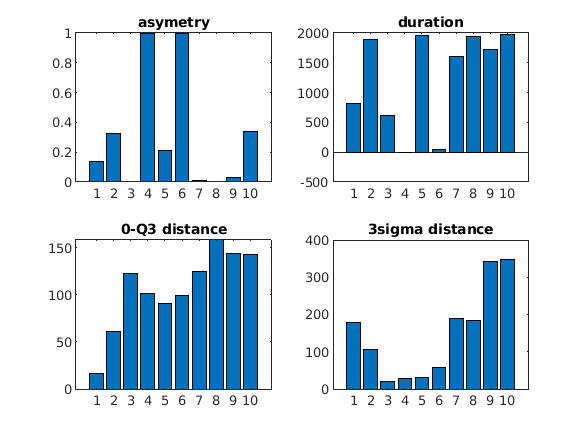


    figure,
    subplot(2,2,1)     
    bar(asym);
    title('asymetry')
    subplot(2,2,2)     
    bar(dur); 
    title('duration')     
    subplot(2,2,3)
    bar(QBINDIST(1: size(fire_n_interv,2)));
    title('0-Q3 distance');
    subplot(2,2,4)
    bar(TrSIGMADIST(1: size(fire_n_interv,2)));
    title('3sigma distance');

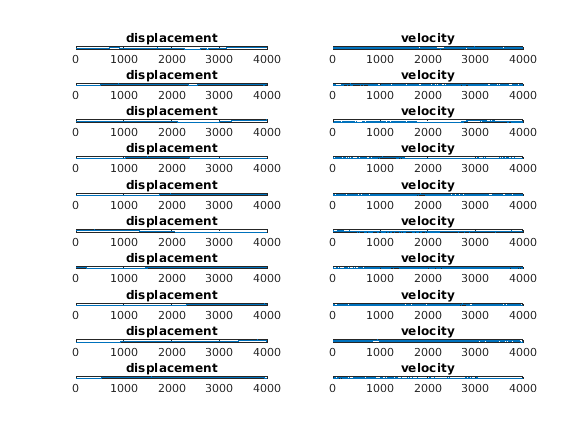

 %   figure,
  %  CORRTF= [chns_rho(NBIN,:),chnsd_rho(NBIN,:),chnsth_rho(NBIN,:),chnsa_rho(NBIN,:),chnsm_rho(NBIN,:),chnss_rho(NBIN,:),chnsb_rho(NBIN,:),chnsg_rho(NBIN,:)];
%    imagesc(CORRTF)
%    title('ACG of the 10 spikes interval on time and frequency domain')
%    colorbar
    
    figure,
    for n = 1:size(fire_n_interv, 2)
        wave = fire_n_interv(:, n);
        N = length(wave);
        if mod(N,2)==1
            v = zeros(2*N-1,1);
            v(1:2:2*N-3) = wave(2:length(wave)) - wave(1:length(wave)-1);
            v(2:2:length(v)-1) = 0.5*v(1:2:length(v)-2)+0.5*v(3:2:length(v));
            s = interp(wave, 2);
        else
            v = zeros(2*N,1);
            v(1:2:2*N-2) = wave(2:length(wave)) - wave(1:length(wave)-1);
            v = [v;v(length(v)-2)];
            v(2:2:length(v)-1) = 0.5*v(1:2:length(v)-2)+0.5*v(3:2:length(v));
            s = interp(wave, 2);
        end
        velocity(:,n) = v;
        displacement(:,n) = s;
        subplot(size(fire_n_interv, 2), 2, 2*n-1)
        plot(s)
        title('displacement')
        subplot(size(fire_n_interv, 2), 2, 2*n)
        plot(v)
        title('velocity')
    end

    
%CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),1),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),2),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),3),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),4),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),5),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),6),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),7),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),8),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),9),CORRTF(1:length(CORRTF)/length(ictal_n_interv):length(CORRTF),10)

MeanCorr = mean(abs(CORRTF),2);
StdCorr = std(abs(CORRTF),0,2);
 

%X = [Q3BIN;QBINDIST; TrSIGMADIST;ictal_n_interv;CORRTF;asym(1:2:length(asym)-1)';asym(2:2:length(asym))';dur(1:2:length(dur)-1)';dur(2:2:length(dur))'];
%X = [NBIN; Q3BIN;QBINDIST; TrSIGMADIST;ictal_n_interv;CORRTF];
X1 = [asym'; dur';NBIN'; Q3BIN(1: size(fire_n_interv,2));QBINDIST(1: size(fire_n_interv,2)); TrSIGMADIST(1: size(fire_n_interv,2));MaxIctal(1: size(fire_n_interv,2));MinIctal(1: size(fire_n_interv,2));StdIctal(1: size(fire_n_interv,2));MeanCorr';StdCorr';asym(1:2:length(asym)-1)';asym(2:2:length(asym))';dur(1:2:length(dur)-1)';dur(2:2:length(dur))';[-1,1,1,-1,-1]];

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

%X(isnan(X))= 0;
X1(isnan(X1))= 0;
X = [asym'; dur'; velocity;NBIN'; Q3BIN(1: size(fire_n_interv,2));QBINDIST(1: size(ictal_n_interv,2)); TrSIGMADIST(1: size(ictal_n_interv,2));MaxIctal(1: size(ictal_n_interv,2));MinIctal(1: size(ictal_n_interv,2));StdIctal(1: size(ictal_n_interv,2));MeanCorr';StdCorr';asym(1:2:length(asym)-1)';asym(2:2:length(asym))';dur(1:2:length(dur)-1)';dur(2:2:length(dur))';[-1,1,1,-1,-1]];
X(isnan(X))= 0;

%%
%[asym_test,dur_test,NBIN_test,Q3BIN_test,QBINDIST_test,TrSIGMADIST_test,fire_n_interv_test,CORRTF_test,MaxIctal_test,MinIctal_test,StdIctal_test,MeanCorr_test,StdCorr_test] = spikes(Pnts, bin, fs, test, MEA_test, MEAy_test, ictals4)
%%

%X = [NBIN; Q3BIN;QBINDIST; TrSIGMADIST;ictal_n_interv;CORRTF];
%X1 = [asym'; dur'; NBIN; Q3BIN;QBINDIST; TrSIGMADIST;MaxIctal;MinIctal;StdIctal;MeanCorr;StdCorr;y];
%X(isnan(X))= 0;
%X1(isnan(X1))= 0;

%R = corr(X);
[p,tbl,stats] = anova1(X1);
[results,means] = multcompare(stats,'CType','bonferroni')

stats=gplotmatrix(X1',[],group,[],'*.')

Tbtimelm = table(X1(1,:)',X1(2,:)',X1(3,:)',X1(4,:)',X1(5,:)',X1(6,:)',X1(7,:)',X1(8,:)',X1(9,:)',X1(10,:)',X1(11,:)',X1(12,:)',X1(13,:)',X1(14,:)',X1(15,:)', group','VariableNames',{'Asymetry','Duration','ictalBIN','Q3BIN','DIST_Q3', 'DIST_3SIGMA','MAXICTAL','MINICTAL','STDICTAL','MEANCORR','STDCORR','StAsymetry','EdAsymetry','StDuration','EdDuration','TYPE'});
Tbtimelm1 = table(X1(1,:)',X1(2,:)',X1(3,:)',X1(4,:)',X1(5,:)',X1(6,:)',X1(7,:)',X1(8,:)',X1(9,:)',X1(10,:)',X1(11,:)',X1(12,:)',X1(13,:)',X1(14,:)',X1(15,:)',X1(16,:)', group','VariableNames',{'Asymetry','Duration','Velocity','ictalBIN','Q3BIN','DIST_Q3', 'DIST_3SIGMA','MAXICTAL','MINICTAL','STDICTAL','MEANCORR','STDCORR','StAsymetry','EdAsymetry','StDuration','EdDuration','TYPE'});

lm1_cor1 = fitlm(Tbtimelm,'TYPE~Duration/Asymetry+StDuration/StAsymetry+EdDuration/EdAsymetry+MEANCORR*STDCORR/DIST_3SIGMA+DIST_Q3')
lm1_cor2 = fitlm(Tbtimelm,'TYPE~Duration/Asymetry+StDuration/StAsymetry+EdDuration/EdAsymetry+DIST_Q3/DIST_3SIGMA')
lm1_cor3 = fitlm(Tbtimelm,'TYPE~Duration+StDuration+EdDuration')
lm1_cor4 = fitlm(Tbtimelm1,'TYPE~Duration+StDuration+EdDuration+Velocity')

Xnew = sort(X1(1:15,:));
ypred = predict(lm1_cor3,Xnew')
%ypred = ypred - 1:10;
ypred(ypred> mean(ypred)) = 1;
ypred(ypred<= mean(ypred)) = -1
%y = [-1,1,1,-1,-1,1,-1,-1,-1,-1];
y
ypred == y';
accuracy = sum(ypred == y')/ length(y)
% % Plot jnjm/m /mthe original responses and the predicted responses to see how they differ.
figure,
plot(1:length(y),y,'o',1:length(y),ypred,'x')
legend('Data','Predictions')
title(['Result of linear regression with accuracy: ',num2str(accuracy)]);


%manovacluster(ictal_n_interv)
% legend('Input Data','Filtered Data')
% 
% plot(interval,MEAy_ch(bin*(n-1)+1:bin*(n-1)+1+length(interval)-1),'r');
% hold on
% plot(interval,MEA_t(bin*(n-1)+1:bin*(n-1)+1+length(interval)-1),'b');
% title(['raw data v.s filtered data on channel', num2str(ch),' ', num2str(n_interv), 'th ictal interval : ', num2str(n),' s to ', num2str(n_end), ' s']);
% legend('Input Data','Filtered Data')
% ictal_n_interv = ictal_n_interv(:, 1:2:size(ictal_n_interv,2));
type = ["interictal","ictal", "ictal", "interictal",  "interictal"];
group = [0,1,1,0,0];
y = [-1,1,1,-1,-1];
%[Asym, Dur, ypred, lml_cor3] = ictalclassify(ictal_n_interv, fs, asym, dur, type, group, y, ch)

% ictal, inter-ictal 
ictal_n_interv = zeros(60000,5);
for i = 1:size(ictals, 1)
    ictal_n_interv(1:length((floor(ictals(i,1))-1)*bin+1: (floor(ictals(i,2))+1)*bin),i) = MEA_t((floor(ictals(i,1))-1)*bin+1: (floor(ictals(i,2))+1)*bin);
end

Unrecognized function or variable 'ictals'.

EEG = ictal_n_interv(1:10:size(ictal_n_interv, 1), :);
%L = size(ictal_n_interv, 2);
%seglen = bin;
%M = ceil(size(ictal_n_interv, 1)/bin);
%a = 0.1;
%FF = RD_STFT(EEG, fs, M, L, seglen, a);%overlap 0.5
[yupper,ylower] = envelope(EEG);
[M, N] = size(EEG); 
SE = zeros(M, N);
SEH = SE;
for i = 1:N
   mdl = fit([1: size(yupper,1)]', 0.5*(yupper(:,i)+ylower(:,i)), 'poly3', 'Normalize','on', 'Robust','Bisquare'); 
   h(:,i) = EEG(:, i)- mdl(1:M);
   k = 1;
   hk(:,k) = abs(h(:,i) - mean(h(:,i) , 1));
   Hk(:,k) = real(hilbert(hk(:,k))); 
   SD = abs(hk(:,k) - abs(hk(:,k)  - mean(hk(:,k) , 1))).^2./abs(hk(:,k) - mean(hk(:,k) , 1)).^2;   
   while  sum(SD > mean(SD))>0.001*i*M & k < M
       hk(:,k+1)  = abs(hk(:,k) - mean(hk(:,k) , 1));
       Hk(:,k+1) = real(hilbert(hk(:,k))); 
       SD = SD + abs(hk(:,k) - abs(hk(:,k+1)  - mean(hk(:,k+1) , 1))).^2./abs(hk(:,k+1) - mean(hk(:,k+1) , 1)).^2;          
       k = k+1;
   end
   if k >1
       SE(:,i) = sum(hk./repmat(sum(hk,2),[1, size(hk,2)]).*log(hk./repmat(sum(hk,2),[1,size(hk,2)])),2);
       SEH(:,i) = sum(Hk./repmat(sum(Hk,2),[1, size(Hk,2)]).*log(Hk./repmat(sum(Hk,2),[1,size(Hk,2)])),2);
   else
       SE(:,i) = hk/sum(hk).*log(hk/sum(hk))+(1-hk/sum(hk)).*log(1-hk/sum(hk));
       SEH(:,i) = Hk/sum(Hk).*log(Hk/sum(Hk))+(1-Hk/sum(Hk)).*log(1-Hk/sum(Hk));
   end
   clear hk Hk SD mdl
end

%hmmm of ictal type 
% logistic regression with regulation
eps0 = 0.01;
w = ones(M, 1)/M;

Unrecognized function or variable 'M'.

lmd = w;
%threshold1 = 80;
%threshold2 = 120;
Pnts = size(ictal_n_interv, 1);

bin = 2000;
%fn = 0:bin-1;
%f = 1.0*double(fn)/double(bin-1);
%t = -0.5:1/bin:0.5;  % Time vector 
%L = length(t)-1;      % Signal length
%X = 1/(4*sqrt(2*pi*0.01))*(exp(-t(1:L).^2/(2*0.01)));
%fX = fft(MEA_ch(1: bin: Pnts)).*X;
%ni = find(MEA_ch > threshold);
steps = 50;  
L = repmat(-100,[M, 1]);
l = zeros(M, N);
ypred = zeros(1, N);
W = zeros(M, N);
B = zeros(M, N);
F_= zeros(M, N);
% Mu = ze(length(ctx), 1);
% Eta = zeros(idN, idN);
% Kse = zeros(idN, idN);
    for k = 1:N
%    k = 1;
%    for k =
%    1:length(ctx)
%    for k = 1:7
%    for k = 59:length(ctx) 
%for k = 54:length(ctx) 
        while steps >0
            SEtemp = SE(:,k); 
            SEtemp = (SEtemp - mean(SEtemp))/std(SEtemp);
            Y = y(k);
            b = gampdf(SEtemp, 0.2, 2);
%             b = ones(length(F_(:, k)),1)./(1 + exp(-F_(:, k) - sigma.*F_hat));
            w = w/(sum(w)+0.000001);
%             wd = 1+exp(-F_);
%             wd(isinf(wd)) = 10000;
%             w = w + mu*F_hat.*wd.^2./(exp(-F_(:, k)).*F_+0.00001);
%             b = b + mu*F_hat.*wd.^2./(exp(-F_(:, k)-sigma.*F_hat).*F_+0.00001);   
            K =  abs(SEtemp); 
            l(1:length(K), k) = log(1 + exp(-Y.* w(1:length(K)).* SEtemp(:))) + lmd(1:length(K)).*w(1:length(K)).^2/2 + 2*K.*b.* SEtemp./(eps0*length(K));
            cond = log(1 + exp(-Y.* w(1:length(K)).* SEtemp)) + lmd(1:length(K)).*w(1:length(K)).^2/2 + 2*K.*b.* SEtemp./(eps0*(1:length(K)))> L(1:length(K));
            if sum(isnan(cond))~= length(cond) & sum(cond==0)~= length(cond)
                W(1:length(K),k) = -Y.*SEtemp./(1 + exp(-Y.* w(1:length(K)).* SEtemp));
            end
            if (sum(isnan(cond))== length(cond) | sum(cond==0)== length(cond)) 
                k = k+1;
                steps = 50;
                break;
            end
            w = W(:, k);
            L = log(1 + exp(-Y.* w(1:length(K)).* SEtemp)) + lmd.*w(1:length(K)).^2/2 + 2.*K.*b(1:length(K)).* SEtemp./(eps0*(1:length(K)));
            steps = steps -1;
            if steps == 0
                l(isnan(l(:,k)),k) = 0.5*l(isnan(l(:,k)),max(k-1,1))+0.5*l(isnan(l(:,k)),min(k+1,N));
                l(sum(isnan(l(:,k)))==size(l,1),k) = 0.5*l(sum(isnan(l(:,k)))==size(l,1),max(k-1,1))+0.5*l(sum(isnan(l(:,k)))==size(l,1),min(k+1,N));
                ypred(1,k) = mean(l(l(:,k)~=0,k));
                k = k+1;
                steps = 50;
                break;
            end
%             if k > length(ctx)
%                  break
%             end
        end
    end
    ypred
 ypred(ypred>mean(ypred)) = 1;
 ypred(ypred<=mean(ypred)) = -1;
 accuracy = (sum(ypred == y))./length(y)
 %
 [h, p] = ttest(ypred , y)
 
  %discrete U-test
  
 pcd = y/max(y);
 yc = ones(1,length(pcd))./(1+exp(-pcd));
 yc1 = ones(1,length(pcd))./(1+exp(-pcd-log(1)));
 
 pred = ypred/max(ypred);
 ycpred = ones(1,length(pred))./(1+exp(-pred));
 ycpred1 = ones(1,length(pred))./(1+exp(-pred-log(1)));

 [h, p] = ttest(yc, ycpred)% h = 1, significantly different

figure,
plot(1:length(y),y,'o',1:length(y),ypred,'x')
legend('Data','Predictions')
title(['Result of linear regression with accuracy: ',num2str(accuracy)]);


%F0
 fa_ac = (yc+pcd).*(ycpred+pred);
 %F01
 fa_ac1 = (yc1+pcd).*(yc1-pcd*log(1));
 %F10
 f1a1_ac = (ycpred-pred*log(1)).*(ycpred+pred);
 %F1
 f1a1_ac1 = (yc-pcd*log(1)).*(ycpred-pred*log(1));

  % fk = (gam(1) - pad(1:4).*log(1.1)).*(gam(2) - pacd(1:4).*log(1.1));
F0 = [mean(fa_ac(:)), mean(fa_ac1(:))];
F1 = [mean(f1a1_ac(1)), mean(f1a1_ac1(1))];
 

nH = sum([ttest(F0(1),F1(1))==0 ,ttest(F0(2),F1(1))==0 ,ttest(F0(1),F1(2))==0 ,ttest(F0(2),F1(2))==0]);
phi =  3/4+0.5*nH/4;
psi = 0.5+0.5*(3/4-1/4);
 
phi_ = mean(F0(:))-mean(F1(:))+0.5
psi_ = max(F0(:)-F1(:))
 
figure,
subplot(4,1,1)
plot(log(fa_ac));
title('00');
subplot(4,1,2)
plot(log(fa_ac1));
title('11');
subplot(4,1,3)
plot(log(f1a1_ac));
title('10');
subplot(4,1,4)
plot(log(f1a1_ac1));
title('11');
figure,
imagesc([F0;F1])
title('phi,psi')